
step = importdata("101734_pot_5deg.log")

step = 1.0e+04 *

    0.7565   -0.0001
       NaN   -0.0001
    0.7628   -0.0001
    0.7630   -0.0001
    0.7633   -0.0001
    0.7635   -0.0001
    0.7637   -0.0001
    0.7639   -0.0001
    0.7641   -0.0001
    0.7643   -0.0001


timeTestStart = 38 % set starting point for graph

timeTestStart = 38

timeSeconds = (step(:,1)./1000)-timeTestStart;
measuredAngle = step(:,2);

hold on
line_colors = [0 0 0; 0.9 0.9 0.9]; % Black and grey (RGB)
set(gca, 'ColorOrder', line_colors);
plot(timeSeconds,measuredAngle,"-");
yline(0, '--', 'LineWidth', 0.5); % zeroline
yline(-0.0872, '--', 'LineWidth', 0.5); %5deg line
yline(-0.035, '.-.', "0.035 rad",'LineWidth', 0.5, 'LabelHorizontalAlignment', 'right'); %5deg line

yline(0.035, '.-.', "0.035 rad",'LineWidth', 0.5, 'LabelHorizontalAlignment', 'right'); %5deg line

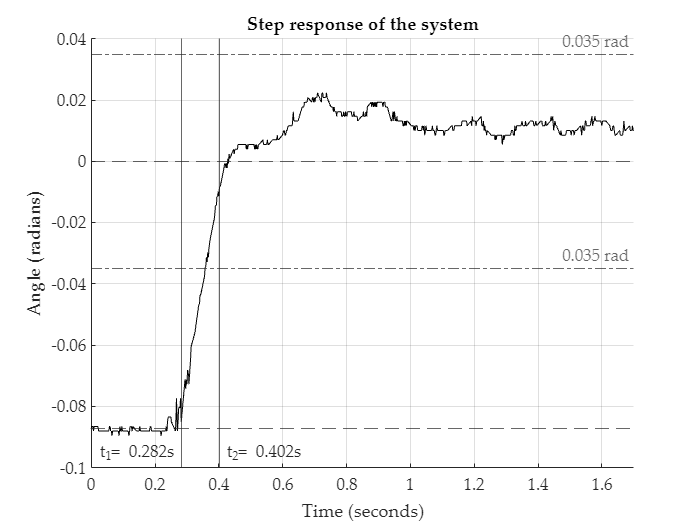

%yline(-0.07848)%
xline(0.282,"-","t_1= 0.282s", 'LabelHorizontalAlignment','left',"LabelVerticalAlignment","bottom","LabelOrientation","horizontal") %vertical line for 10%
%yline(-0.00872)
xline(0.4017,"-","t_2= 0.402s", 'LabelHorizontalAlignment','right',"LabelVerticalAlignment","bottom","LabelOrientation","horizontal") %vertical line for 90%
title 'Step response of the system'
xlabel 'Time (seconds)'
ylabel 'Angle (radians)'
grid on
xlim([0 1.7]);
set(findall(gca, '-property', 'FontName'), FontName="Palatino Linotype");
hold off
f = gcf;
exportgraphics(f,'5Degree_step.pdf','Resolution',1200)